# Labo2 - La corrélation des signaux discrets

**But du laboratoire :** Apprendre l’utilisation de la corrélation sur des signaux discrets par des exemples pratiques. Utiliser la corrélation pour détecter la périodicité d’un signal noyé dans le bruit. Vérifier la relation entre la corrélation et la convolution. Utiliser la fonction de corrélation fournie par Matlab.

## Rappel et définition

**Inter-corrélation **On considère deux signaux x et y qui sont à énergie finie. L’inter-corrélation de ces signaux est la séquence *rxy[k]* définie par :


$$r_{\textrm{xy}} \left\lbrack k\right\rbrack =\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack y\left\lbrack n+k\right\rbrack$$


La notation *rxy* signifie : *x* corrélé avec *y* (x ne bouge pas et y se déplace de droite à gauche pour k positif). D’un point de vue mathématique l’inter-corrélation est le produit scalaire de *x* par *y* décalé. Si ces signaux sont orthogonaux, ou non corrélés, pour chaque valeur de k alors la séquence d’inter-corrélation s’annule. Dans la cas contraire si ces signaux sont identiques alors la corrélation est maximale.

L’inter-corrélation se traduit par cross-correlation en Anglais. On utilise la terminologie Anglaise dans les logiciels mathématiques et dans les librairies de programmation.

**Auto-corrélation** Dans le cas particulier où *x[n] = y[n*] on définit l’auto-corrélation de *x[n]* par :


$$r_{\textrm{xx}} \left\lbrack k\right\rbrack =\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack x\left\lbrack n+k\right\rbrack$$


Lorsque k = 0 on obtient :


$$r_{\textrm{xx}} \left\lbrack 0\right\rbrack =\sum_{n=-\infty }^{\infty } x^2 \left\lbrack n\right\rbrack =W_x$$


## Relation entre la convolution et la corrélation (ex1)

Dans le cours, on a mis en évidence le fait que la corrélation et la convolution sont liées :


$$r_{\mathrm{xy}} \left\lbrack k\right\rbrack =x\left\lbrack -k\right\rbrack *y\left\lbrack k\right\rbrack$$


ou de manière équivalente :


$$r_{\textrm{yx}} \left\lbrack k\right\rbrack =x\left\lbrack k\right\rbrack *y\left\lbrack -k\right\rbrack$$


et les propriétés suivantes sont valables :

- Inversion de x,y :


$$r_{\mathrm{xy}} \left\lbrack k\right\rbrack =r_{\mathrm{yx}} \left\lbrack -k\right\rbrack$$


- Parité de l’auto-corrélation (dans le cas de x réel) :


$$r_{\textrm{xx}} \left\lbrack k\right\rbrack =r_{\textrm{xx}} \left\lbrack -k\right\rbrack$$


**Expérimentation :**

- Montrez à l’aide de Matlab que la relation $r_{\textrm{xy}} \left\lbrack k\right\rbrack =x\left\lbrack -k\right\rbrack *y\left\lbrack k\right\rbrack$ est vérifiée avec : x = [0, 1, 1, 0, 0, 0, 0, 0, 0, 0] et y = [0, 0, 0, 2, 2, 0, 0, 0, 0, 0]. Utilisez la fonction de convolution que vous avez codés dans le Labo 1. Le résultat de la corrélation peut être vérifié sans Matlab.

- En partant de la fonction de convolution réalisée dans le laboratoire précédent réalisez une nouvelle fonction *[rxy,Lag] = MyCorr(x,y)*, qui calcule la corrélation entre un signal x et un signal y (les deux longueurs ne sont pas forcement les mêmes).

% votre code

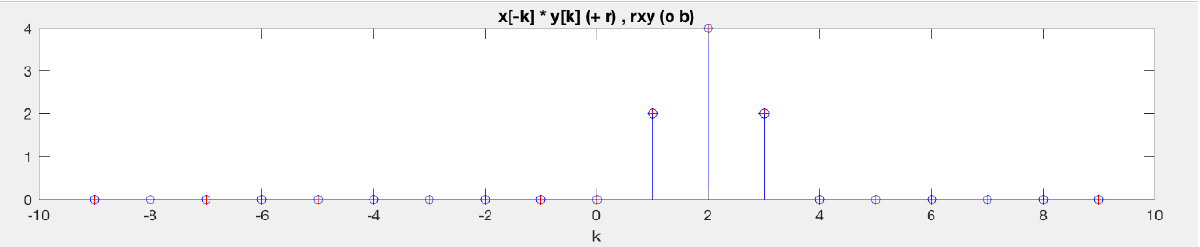

### Utilisation de la fonction *xcorr()* de Matlab (ex2)

Matlab met à disposition une fonction pour le calcul de la corrélation qui se nomme *xcorr()*. Consultez la documentation interactive avec doc xcorr et calculez la corrélation entre x et y précédemment donnés.

La fonction xcorr a deux vecteurs de sortie, la corrélation et le vecteur qui indique les décalages temporels entre les deux signaux, vous remarquerez que les décalages (lags) sont toujours centrés en 0 (pas de décalage). Le max du décalage correspond à la longueur du signal le plus long N - 1.

Attention : Dans la fonction *xcorr(x,y)* c’est x qui est décalé pour un lag positif à gauche. Si on veut selon la définition *rxy[k] =xcorr(y,x)*.

- Construisez les signaux x et y tel qu'affiché sur la figure de dessous.

- Calculez l'intercorrelation avec votre fonction *mycorr* et la fonction matlab *xcorr. *

- Comparez les résultats graphiquement.

% votre code

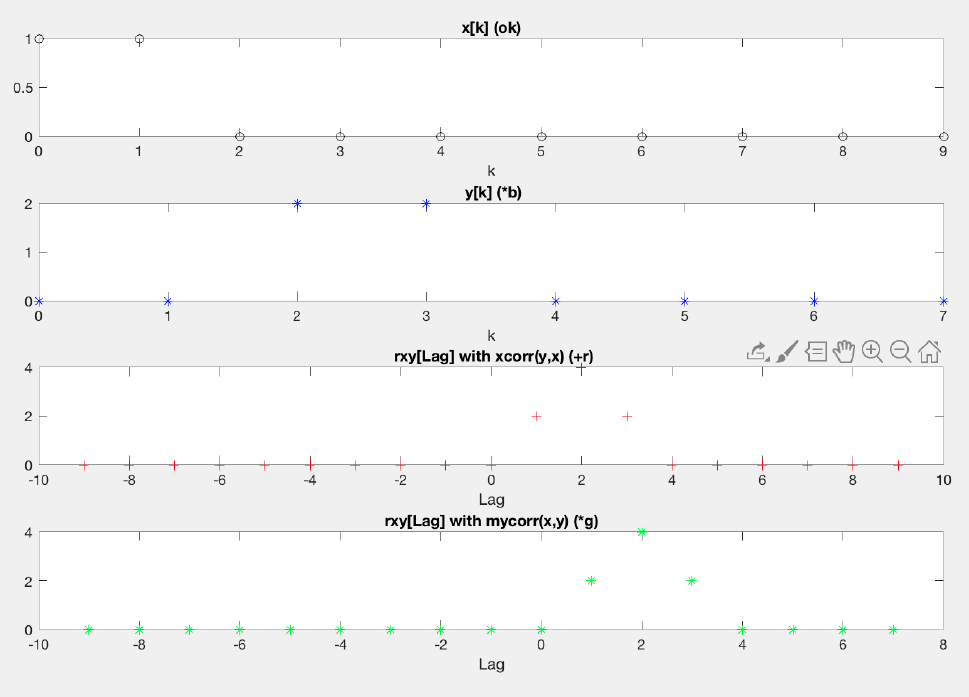

## Auto-Corrélation d’un signal périodique tronqué (ex3)

A l'aide de la fonction sie() utilisée dans le laboratoire précédent, synthétisez un signal périodique d’impulsions exponentielles, de période 0.5 [s] , Tau = 0.1 [s] amplitude 1 [V], la période d’échantillonnage est de 10 [ms] et l’enregistrement dure 10 [s].

- Calculez et affichez l’auto-corrélation de ce signal.

- A partir de l’auto-corrélation, déterminez la périodicité du signal et vérifiez que cela correspond au signal synthétisé.

- Quel est l’énergie de ce signal ?

- Si à la place de la fonction sie vous utilisez la fonction sinam avec Tp = 50 [ms] , que remarquez vous dans l’auto-corrélation? Expliquez.

- Ensuite calculez l’inter-corrélation entre un signal sinusoïdal d’une durée de 10 [s] et depériode 0.1 s avec Te = 10 ms et un autre sinus : identique (auto-corrélation), avec une fréquence légèrement différente , ou une phase différente du premier mais avec une amplitude identique. Quels effets sur la corrélation ?

% votre code

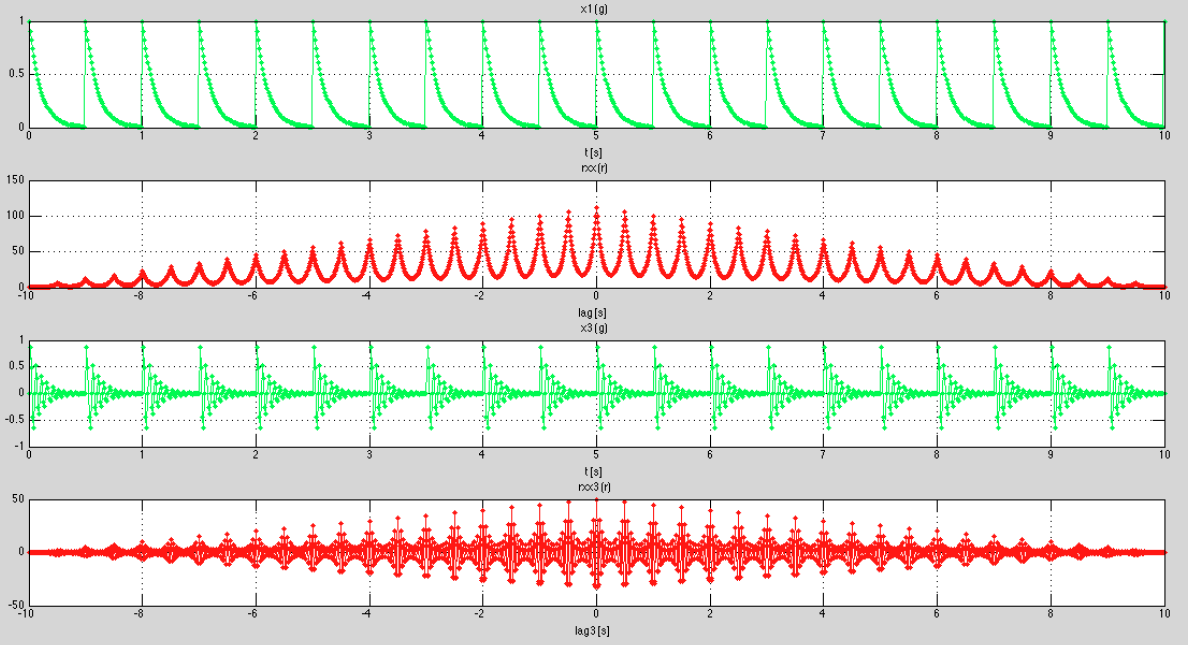

## Détection d’une composante périodique noyé dans le bruit (ex4)

Dans cette partie il s’agit d'étudier un signal fortement bruité à l’aide de la corrélation, le signal non bruité *s[k]* n’est pas connu, mais il est périodique. A l’aide de la corrélation il sera possible d’estimer la fréquence du 

signal s[k] et son énergie. Il sera alors possible de déterminer la forme et la phase du signal s[k] en utilisant la corrélation entre le signal bruité et plusieurs signaux candidats.....

- Avec l’instruction *load(’signalbruite.mat’)* chargez les variables contenues dans ce fichier dans Matlab.

- Calculez et affichez l’auto-corrélation du signal bruité *sn*, observez et déterminez l’énergie du signal bruité ainsi que la meilleure estimation possible de la période $T_{\mathrm{est}}$ du signal non bruité.

- Réalisez un signal $s_{\textrm{est}} \left\lbrack k\right\rbrack =\sin \left(2\pi /T_{\textrm{est}} \left(t-\textrm{tD}\right)\right)$ et calculez la corrélation avec le signal bruité en normalisant ces deux signaux. Afin d’estimer au mieux les deux paramètres $T_{\textrm{est}}$ et *tD*, faites d’abord varier $T_{\mathrm{est}}$ autours de la valeur trouvée au point précédent (de quelques centièmes de secondes en plus ou en moins) afin de trouver une inter-corrélation proche de celle obtenue entre deux sinus de la même fréquence. Ensuite faites varier *tD* pour avoir le maximum de corrélation pour un lag = 0.

- Pour estimer l’amplitude du signal caché il faut faire varier l’amplitude de $s_{\textrm{est}}$, créer un nouveau signal $n_{\textrm{est}} =\textrm{sn}-s_{\textrm{est}}$ et d’en prendre l’auto-corrélation ($r_{\textrm{nn}}$). Lorsque vous aurez trouvé la bonne amplitude, les maximums dus au signal caché auront totalement disparus de l’ auto-corrélation $r_{\textrm{nn}}$.

Attention : Cette méthode permet de faire une estimation du signal caché en faisant l’hypothèse qu’il est de forme sinusoïdale.

% votre code